a=load('D:\TUM\class\23SS\Monty_matlab\group work\group-3\Measured_Date\new_measured\Group3_Walk32_S.mat')

a = 包含以下字段的 struct :
    data: [3×1769 double]
    time: [1×1769 double]


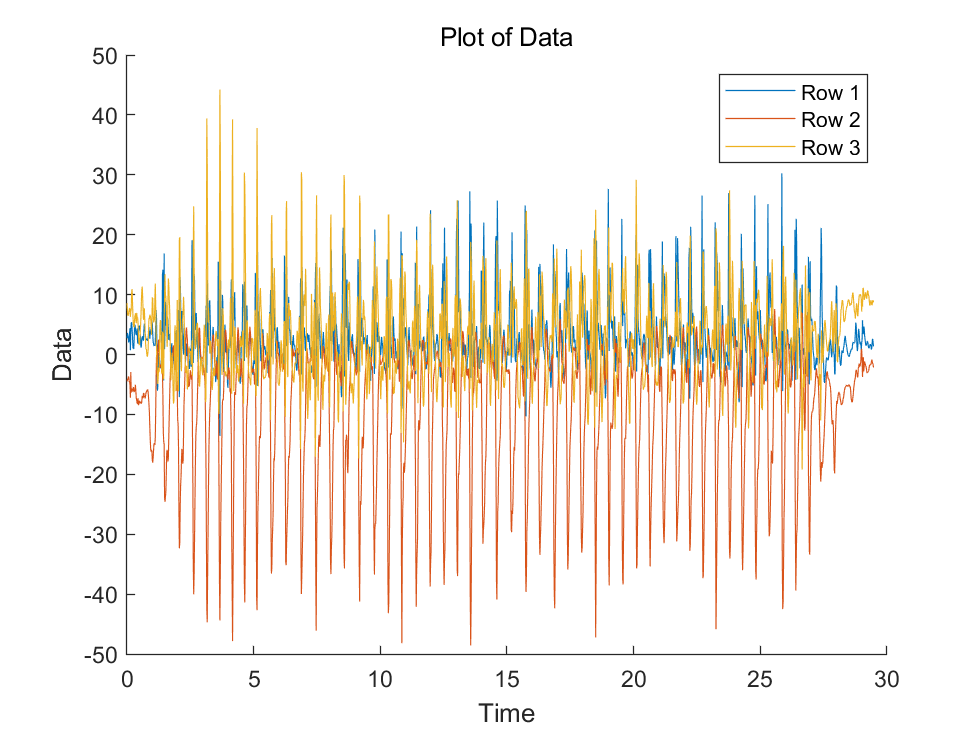

time = a.time;
data = a.data;  % 假设 a 中的 data 变量名为 data
figure;  % 创建一个新的图形窗口

hold on;  % 开启保持绘图状态，以便将多个曲线绘制在同一张图上
for i = 1:size(data, 1)
    plot(time, data(i, :));  % 绘制第 i 行数据
end
hold off;  % 关闭保持绘图状态

xlabel('Time');  % 设置 x 轴标签
ylabel('Data');  % 设置 y 轴标签
title('Plot of Data');  % 设置图标题
legend('Row 1', 'Row 2', 'Row 3');  % 添加图例，显示每一行数据的标识

n = 200;  % 要去掉的数据点的数量
m= 200;

data = data(:, n+1:end-m);  % 选择第 n+1 到最后的数据点
time = time(n+1:end-m);  % 选择第 n+1 到最后的时间点
start_time = time(1);
time= time - start_time;

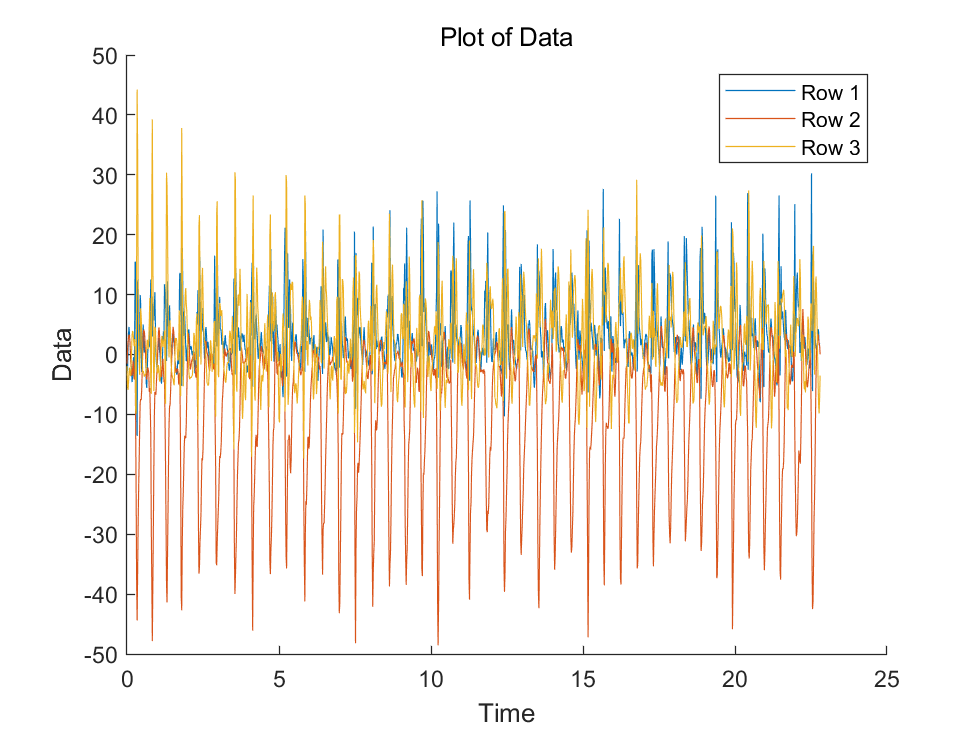

figure;  % 创建一个新的图形窗口

hold on;  % 开启保持绘图状态，以便将多个曲线绘制在同一张图上
for i = 1:size(data, 1)
    plot(time, data(i, :));  % 绘制第 i 行数据
end
hold off;  % 关闭保持绘图状态

xlabel('Time');  % 设置 x 轴标签
ylabel('Data');  % 设置 y 轴标签
title('Plot of Data');  % 设置图标题
legend('Row 1', 'Row 2', 'Row 3');  % 添加图例，显示每一行数据的标识

folder = 'D:\TUM\class\23SS\Monty_matlab\group work\group-3\Preprocessed_Data\Group3_Walk24_S.mat';  % 要保存的文件夹路径

save(folder, 'data', 'time');